clc;
clear;
close all;

## Esercizio 1

generi un numero n intero positivo pari tra 10 e 20 in modo pseudo-random e costruisca e visualizzi la matrice

dove A1 , A2 , A3 e A4 hanno dimensione $\frac{n}{2}\times \frac{n}{2}$ e sono fatte nel seguente modo:

• A1 contiene tutti i valori uguali a 1;

• A2 contiene tutti i valori uguali a 2;

• A3 contiene tutti i valori uguali a 0;

• A4 contiene tutti i valori uguali a 1;

Infine, si calcolino e si visualizzino il determinante di A, il suo raggio spettrale e i numeri di condizionamento con indice 1, 2 e ∞;

n = randi([5 10]) * 2

n = 18


A1 = ones(n/2);
A2 = A1 .* 2;
A3 = zeros(n/2);
A4 = A1;

A = [A1 A2; A3 A4];

Determinante = det(A)

Determinante = 0


[V, D] = eig(A);
D = diag(D);
RaggioSpettrale = max(abs(D))

RaggioSpettrale = 9


Norma1 = norm(A, 1)

Norma1 = 27

Norma2 = norm(A)

Norma2 = 21.7279

NormaInf = norm(A, inf)

NormaInf = 27

clc;
clear;
close all;

## Esercizio 2

crei la matrice dei coefficienti di un sistema lineare Ax = b con numeri pseudo-casuali reali compresi tra −100 e 100 di dimensione 100 × 100 e controlli se è invertibile.

In caso positivo, imponga una soluzione nota x di elementi uguali a 1 e calcoli il corrispondente termine noto b. Successivamente, risolva il sistema lineare utilizzando l’algoritmo di Gauss con pivoting. Infine, calcoli e visualizzi l’errore relativo tra la soluzione vera x e quella ottenuta x1 . Se la matrice A non dovesse risultare invertibile, dovrà esserne generata una nuova fino a quando si ottiene una matrice non singolare;

iMax = 100;
iMin = -100;
n = 100;
flag = true;

while flag
    A = (iMax-iMin) * rand(n) + iMin;
    if det(A) < 10e-5
        disp("La matrice non e' invertibile");
    else
        flag = false;

        x = ones(n, 1);
        b = A * x;

        [U, b2] = gauss_p(A, b);
        x1 = U \ b2;

        errRel = norm(x - x1) / norm(x)
    end
end

La matrice non e' invertibile


errRel = 1.3366e-14

clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

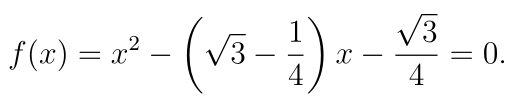

utilizzando il metodo delle corde, con punto iniziale x0 = 1, e con il metodo delle secanti, con x0 = 1 e x1 = 2. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le due approssimazioni ottenute.

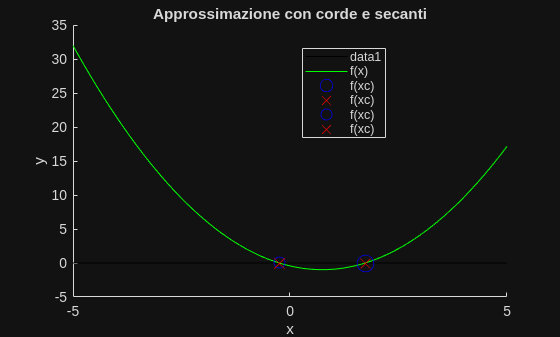

tau = 10e-5;
kmax = 100;

f = @(x) x.^2 - (sqrt(3) - 1/4).*x - sqrt(3)/4;
f1 = @(x) 2.*x - (sqrt(3) - 1/4);

x0 = 1;
x1 = 2;

[xs, ks] = secanti(f, x0, x1, 10e-5, 100);
[xc, kc] = corde(f, f1(x1), x0, 10e-5, 100);

[xs2, ks2] = secanti(f, -1, 1, 10e-5, 100);
[xc2, kc2] = corde(f, f1(-1), -1, 10e-5, 100);

x = linspace(-5, +5, 100);

figure;
hold on;

title("Approssimazione con corde e secanti")

plot(x, zeros(size(x)), "-k");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xc, f(xc), "Ob", "DisplayName", "f(xc)", "MarkerSize", 12);
plot(xs, f(xs), "xr", "DisplayName", "f(xc)", "MarkerSize", 10);
plot(xc2, f(xc2), "Ob", "DisplayName", "f(xc)", "MarkerSize", 8);
plot(xs2, f(xs2), "xr", "DisplayName", "f(xc)", "MarkerSize", 11);

ylabel("y");
xlabel("x");

legend("Location", "best");

hold off;

function [U, b2] = gauss_p(A, b)

    % gauss_p: funzione che calcola la riduzione di Gauss con pivoting e 
    % prende in ingresso la matrice A e il vettore di termini noti b.
    % [U, b2] = gauss_p(A, b) restituisce la riduzione di Gauss, non i 
    % termini noti

    % Controlli preliminari sulle dimensioni di matrice, vettore e sul
    % determinante di A
    [m, n] = size(A);
    if m ~= n
        error("la matrice deve essere quadrata");
    end
    if size(b, 1) ~= n || size(b, 2) ~= 1
        error("b deve essere un vettore colonna con n righe");
    end
    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end


    for k = 1 : n-1

        [~, pos] = max(abs(A(k:n,k))); % Prendo le righe da k in giù nella colonna corrente
        % In pratica scarto il valore e prendo solo la posizione

        % Però ho il valore nel vettore che sto considerando, non della
        % matrice originale:
        l = pos + k - 1;

        % E poi scambio le righe:
        % Prendo la riga k E la riga l
        A([k l], :) = A([l k], :);
        b([k l]) = b([l k]);


        for i = k+1 : n
            m = A(i, k) / A(k, k);

            % Calcolo della nuova riga per ottenere una triangolare
            % inferiore
            A(i, :) = A(i, :) - m * A(k, :);

            b(i) = b(i) - m * b(k);
        end
    end

    % Assegno il valore corretto alle matrici da restituire
    U = A;
    b2 = b;
end

function [xc, kc] = corde(f, m, x0, tau, kmax)
    
    % corde: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xc, kc] = corde(f, m, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Controllo che il punto iniziale sia già una radice
    if(abs(f(x0)) < tau)
        xc = x0;
        kc = 1;
        return;
    end
    
    % Controllo che m non sia tendente a 0
    if abs(m) < tau
        error("Valore di m troppo vicino a 0");
    end

    % Inizio algoritmo iterativo da k a kmax
    for kc = 1 : kmax

        % Formula corde
        xc = x0 - f(x0) / m;

        % Condizioni di arresto
        if abs(f(xc)) < tau || abs(xc - x0) < tau * abs(x0)
            return;
        end

        % Aggiorno variabile
        x0 = xc;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xs, ks] = secanti(f, x0, x1, tau, kmax)

    % secanti: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [x, k] = secanti(f, x0, x1, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Caso base: x0 è già una soluzione
    if abs(f(x0)) < tau
        xs = x0;
        ks = 0;
        return
    end


    % Inizio algoritmo iterativo da 1 a kmax con passo 1
    for ks = 1 : kmax

        % Controllo che i punti non siano gli stessi
        if x0 == x1
            error("Divisione per 0, modifica x0 e x1");
        end
        
        f0 = f(x0);
        f1 = f(x1);
        
        % Formula secanti
        m = (f1 - f0) / (x1 - x0);
        x_new = x1 - f1 / m;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(x_new - x1) < tau * abs(x1) || abs(f(x_new)) < tau
            xs = x_new;
            return;
        end

        % Aggiorno i punti
        x0 = x1;
        x1 = x_new;
    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    xs = x_new;
    warning("Iterazioni massime raggiunte");
   
end